clc,clear,close all;
figure;
n=-20:100;
x1=cos(pi*n/4)+1i*sin(pi*n/4);
x2=sin(pi*n/8+pi/16);
x3=(9/10).^n;
x4=n+1;
subplot(4,1,1),stem(n,x1),title('x1[n]=cos(pi*n/4)+i*sin(pi*n/4)');

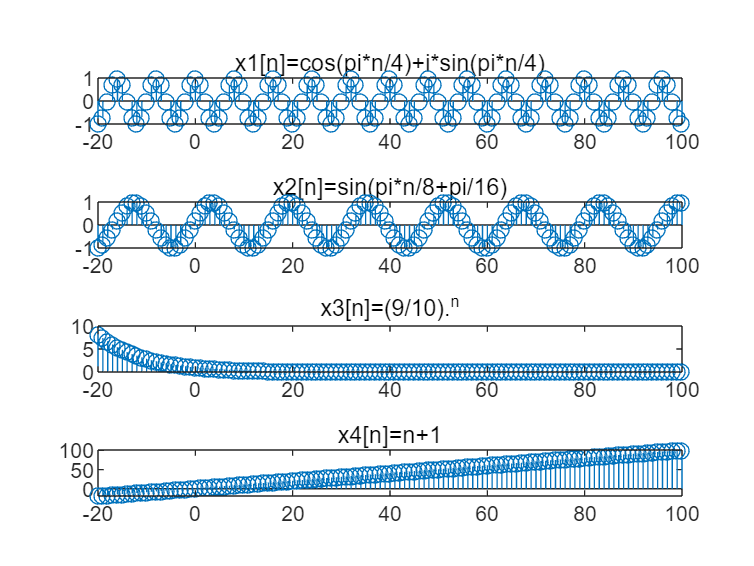

subplot(4,1,2),stem(n,x2),title('x2[n]=sin(pi*n/8+pi/16)');
subplot(4,1,3),stem(n,x3),title('x3[n]=(9/10).^n');
subplot(4,1,4),stem(n,x4),title('x4[n]=n+1');

figure;
a=[1 -0.25];
b=[1 0.9];
y1=filter(b,a,x1);
y2=filter(b,a,x2);
y3=filter(b,a,x3);
y4=filter(b,a,x4);
subplot(4,1,1),stem(n,y1),title('y1[n]'),xlim([0 100]);

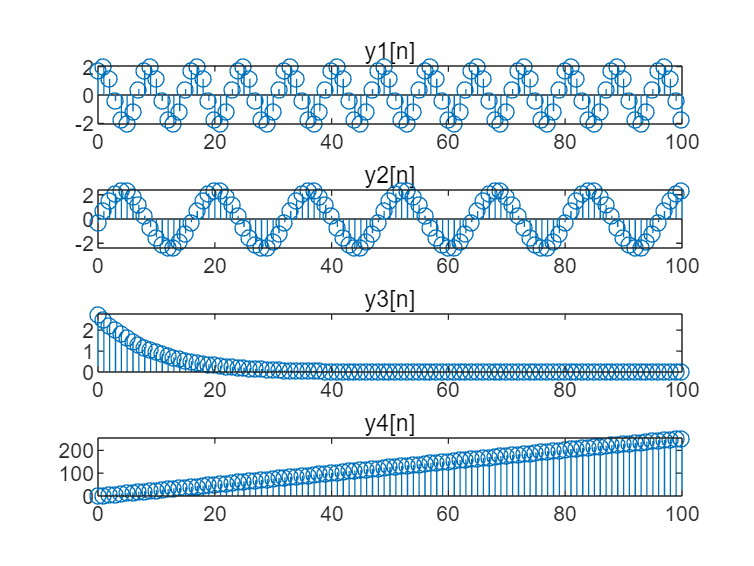

subplot(4,1,2),stem(n,y2),title('y2[n]'),xlim([0 100]);
subplot(4,1,3),stem(n,y3),title('y3[n]'),xlim([0 100]);
subplot(4,1,4),stem(n,y4),title('y4[n]'),xlim([0 100]);

figure;
H1=y1./x1;
H2=y2./x2;
H3=y3./x3;
H4=y4./x4;
subplot(4,1,1),stem(n,H1),title('H1'),xlim([0 100]);

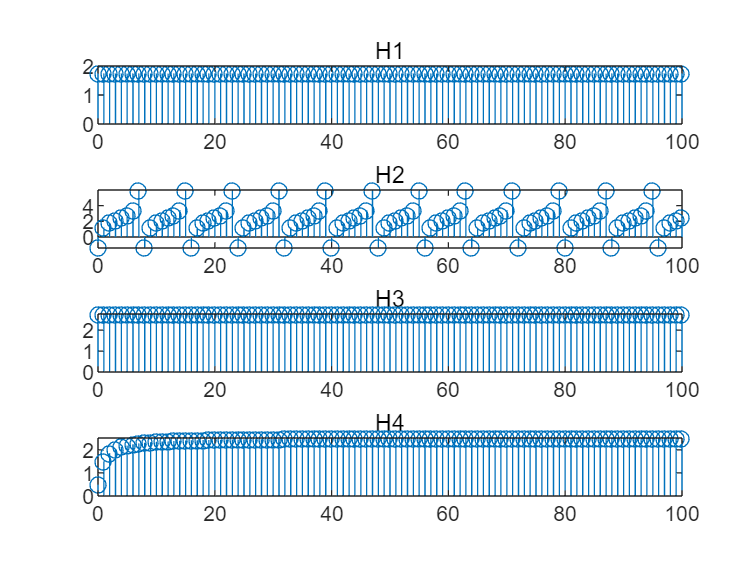

subplot(4,1,2),stem(n,H2),title('H2'),xlim([0 100]);
subplot(4,1,3),stem(n,H3),title('H3'),xlim([0 100]);
subplot(4,1,4),stem(n,H4),title('H4'),xlim([0 100]);

clc,clear,close all;
n=[0 1];
x=[0 1];
h1=x.*exp(-1i*pi*n);
a0=1/2*sum(x);
a1=1/2*sum(h1);

clc,clear,close all;
x=[zeros(1,20) ones(1,20)];
nx=0:1:39;
N=40;
a=[];
for i=0:39
    temp=0;
    for j=0:39
        h=x(j+1).*exp(-1i*2*pi*j*i/N);
        temp=temp+sum(h);
    end
    a=[a temp/N];
end

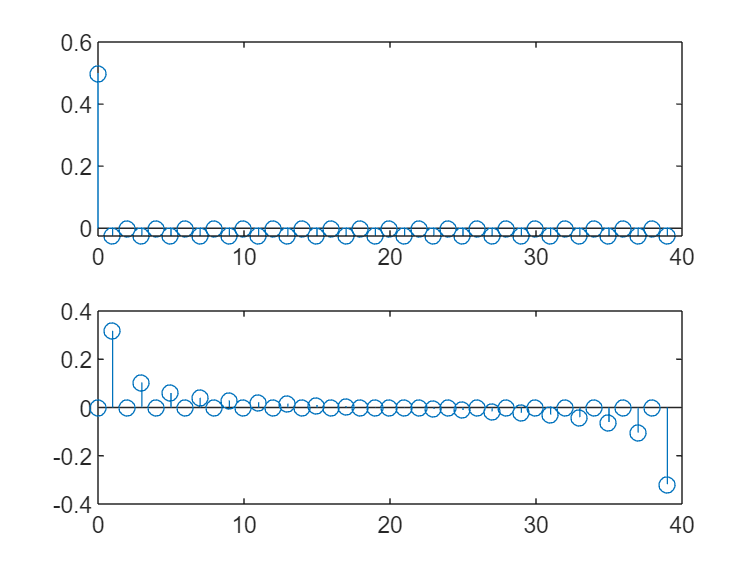

figure;
subplot(2,1,1),stem(nx,real(a));
subplot(2,1,2),stem(nx,imag(a));

x=[zeros(1,20) ones(1,20)];
nx=0:1:39;
N=40;
b=fft(x)/N;%fft得到a
figure;
subplot(2,1,1),stem(nx,real(b));
subplot(2,1,2),stem(nx,imag(b));

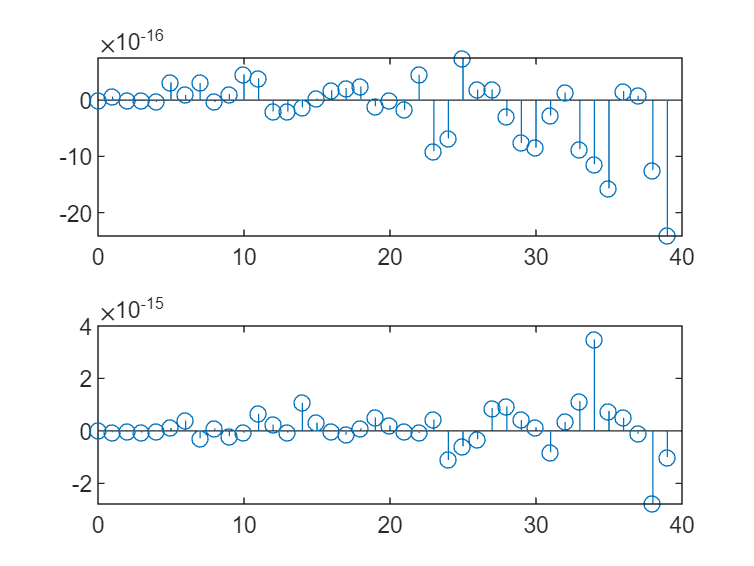

figure;
subplot(2,1,1),stem(nx,real(b)-real(a));
subplot(2,1,2),stem(nx,imag(b)-imag(a));

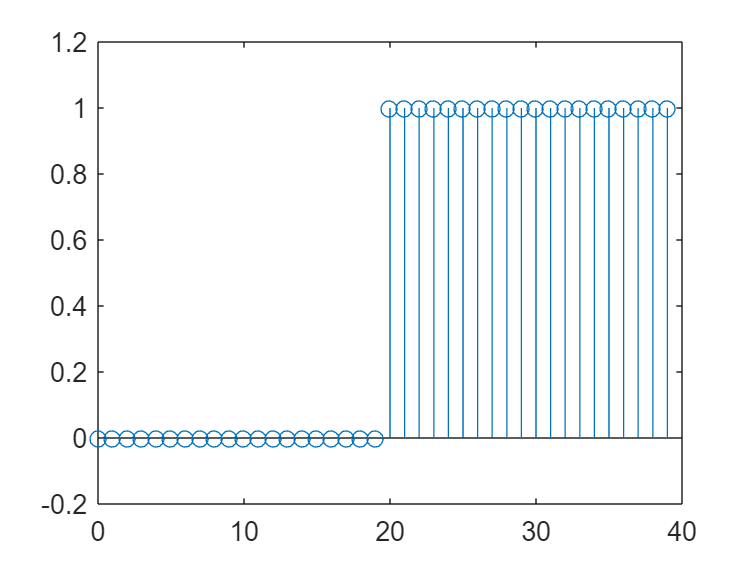

y=N*ifft(a);%ifft得到x
figure;
stem(nx,y);

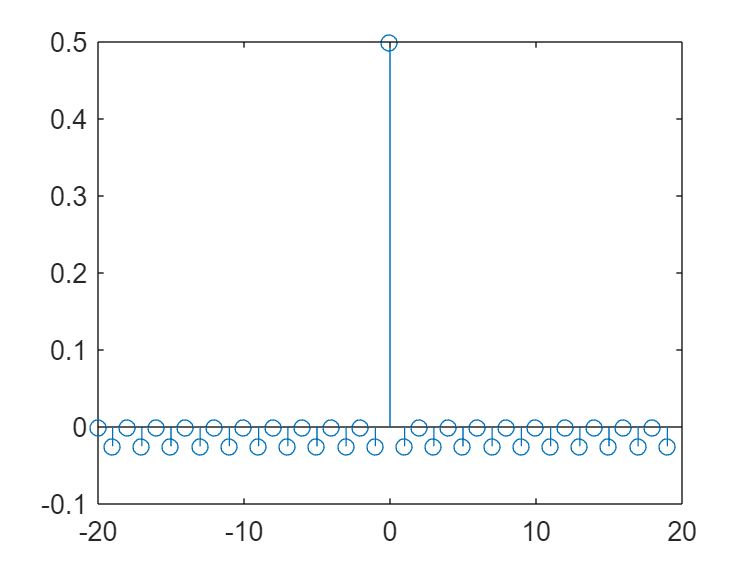

figure;
stem(nx-N/2,fftshift(a));%移到以0为中心点%%如果N为奇数，-(N-1/2)